# Homework #6

Author: Victoria Subritzky Katz

Date: 09/22/2023

## Q1

num_sim = 1000; 
p_values = NaN(1,num_sim);
alpha = .05; 
MU2_versions = [1,2,10];
for j = 1:length(MU2_versions)
% Define params for normal distributions 
MU1 = 1;
MU2 = MU2_versions(j);
SIGMA = 1;

for i = 1:num_sim

% Get random samples, same n
N = 100;
X1 = normrnd(MU1, SIGMA, N, 1);
X2 = normrnd(MU2, SIGMA, N, 1);

% Compute test statistic
Sp = sqrt((var(X1) + var(X2))./2);
tU = (mean(X1)-mean(X2))./(Sp.*sqrt(2./N));

% The p-value is the probabilty of obtaining the t-statistic under the
% null hypothesis; that is, 1 minus the cdf of the t-distribution, given
% n-1 degrees of freedom (multiplied by two because we are looking at two
% symmetric tails)
pU = 2.*(1-tcdf(abs(tU), 2*N-2));
p_values(i) =pU;

% Compare to what we get from ttest
[~,PU,~,STATSU] = ttest2(X1, X2);

end

figure
histogram(p_values)
title('P-values from 1000 Simulations Comparing Normal Distributions (using Two Tailed Unpaired t-Test)')
xlabel('P-Value')
ylabel('Frequency')

sig_pValues = p_values(p_values < alpha); 
fprintf('There are %2d significant p-values without correction for MU1=1 & MU2=%2d\n', length(sig_pValues),MU2)

## Q2

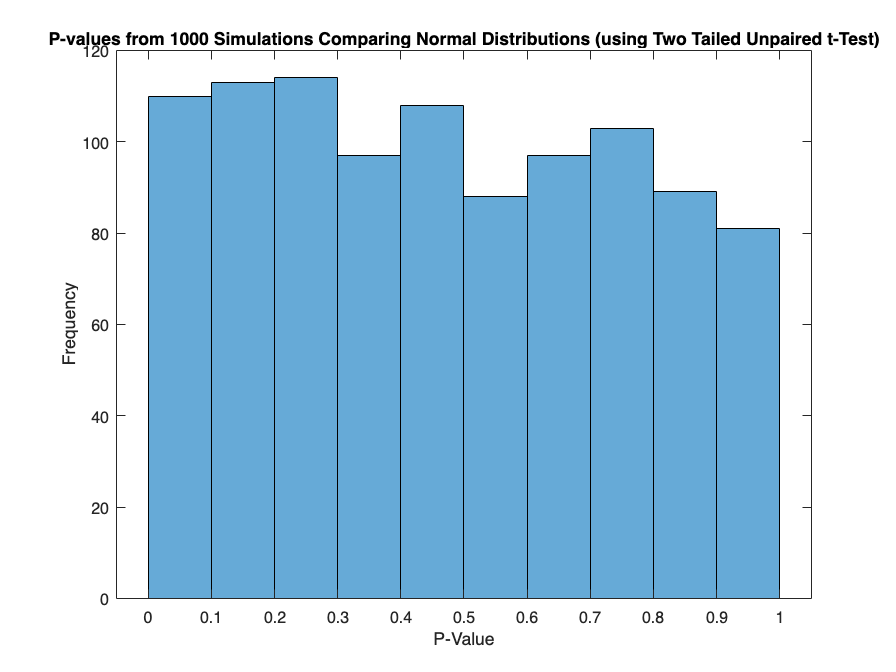

There are 53 significant p-values without correction for MU1=1 & MU2= 1


There are  0 significant p-values using the Bonferroni correction method for MU1=1 & MU2= 1


There are  0 significant p-values using the Benjamini–Hochberg correction method for MU1=1 & MU2= 1


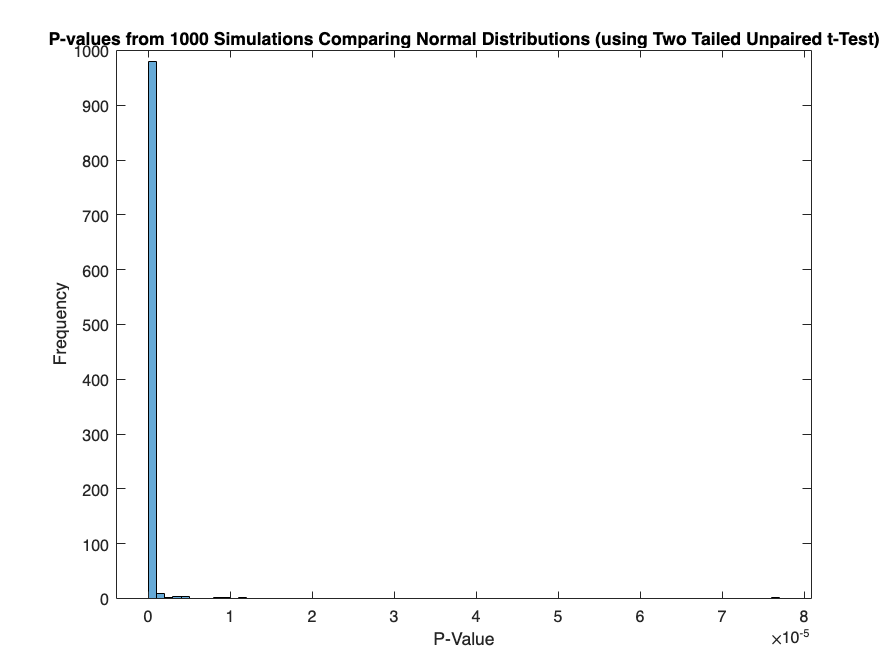

There are 1000 significant p-values without correction for MU1=1 & MU2= 2


There are 999 significant p-values using the Bonferroni correction method for MU1=1 & MU2= 2


There are 999 significant p-values using the Benjamini–Hochberg correction method for MU1=1 & MU2= 2


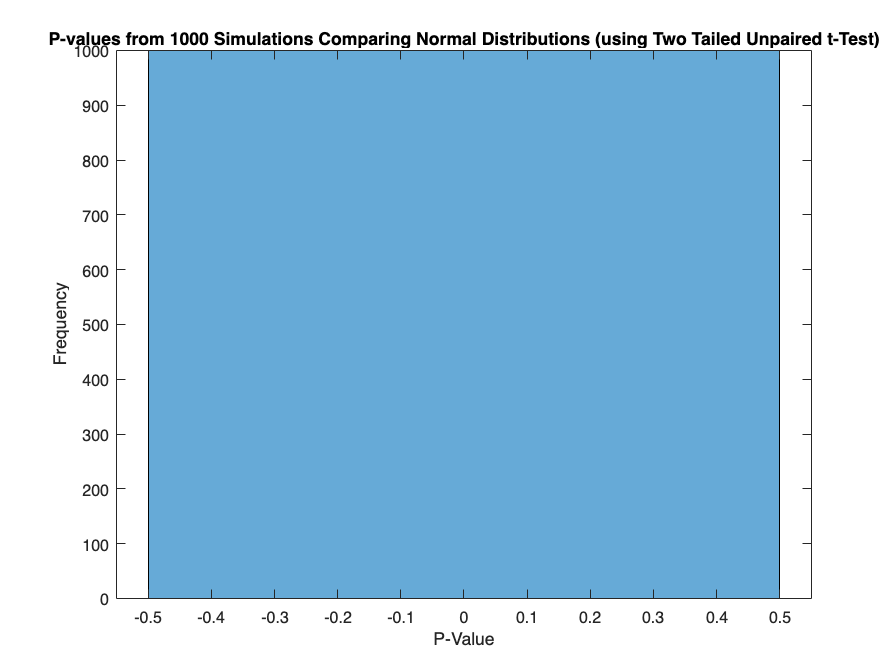

There are 1000 significant p-values without correction for MU1=1 & MU2=10


There are 1000 significant p-values using the Bonferroni correction method for MU1=1 & MU2=10


There are  0 significant p-values using the Benjamini–Hochberg correction method for MU1=1 & MU2=10



%% Bonferroni Correction Method
bonferroni_corrected_alpha = alpha/num_sim; 
sig_pValues_bonferroni = p_values(p_values < bonferroni_corrected_alpha);  %determing which p-values meet the new criterion 

fprintf('There are %2d significant p-values using the Bonferroni correction method for MU1=1 & MU2=%2d\n', length(sig_pValues_bonferroni),MU2)


%%Benjamini–Hochberg Correction Method
critical_value = NaN(1,num_sim); 
new_criterion = -1; %arbitrarily low start value for new criterion

p_values_sort = sort(p_values); 
for i = 1:length(p_values)
    critical_value(i) = (i/num_sim)*alpha; %calculating critical value for each p-value
    if p_values_sort(i) < critical_value(i) && p_values_sort(i) > new_criterion  %checking if codnitions are met to set new criterion value
        new_criterion = p_values_sort(i);
        %when the MU values are the same this condition is never triggered,
        %so the new criterion gets left at the arbitrarily low value i set
        %it at before.Not sure what the correct method is to handle that.
        %Additionally, when I make MU2 too big than MATLAB rounds teh tiny
        %number resulting from the disvision to 0, which also messes it up.
    end
end


sig_pValues_BH = p_values(p_values < new_criterion); %determing which p-values meet the new criterion 

fprintf('There are %2d significant p-values using the Benjamini–Hochberg correction method for MU1=1 & MU2=%2d\n', length(sig_pValues_BH),MU2)

end

## Q3

Adjusting the samplpe means to be 1 & 2 results in all the p-values being significant, which makes sense given that we should reject the null hypothesis that the samples come from dsitribtiions of equal means, as now they do not. Correcting using either the Bonferrroni or Benjamin-Hochberg methods result in a few simulations being termed no longer significant but does not have a larger effect. Bumping the difference in means up more results in the Bonferrroni and the Benjamin-Hochberg correction methods having no effect. 